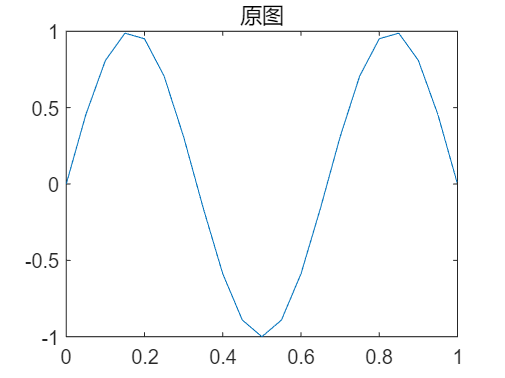

clc,clear,close all

f = @(x) sin(3*pi*x);


sigma = 0.005;
n = 50;
hh = 0.05;
varphi = @(r) r;
x1 = 0;    % x的下限
x2 = 1;    % x的上限

x = unifrnd(x1,x2,[n,1]);   % 已知点的x坐标
y = f(x);
h = 0.05;
xx = 0:h:1;

A = zeros(length(x));
for i = 1:length(x)
    for j = 1:length(x)
        r = abs(x(i) - x(j));
        A(i,j) = varphi(r);
    end
end
b = y;
w = A\b;

yy = zeros(1,length(xx));
for i = 1:length(xx)
    r = zeros(n,1);
    for k = 1:n
        r(k) = abs(x(k)-xx(i));
    end
    yy(i) = sum(w.*r);
end

plot(xx,f(xx))
title('原图')

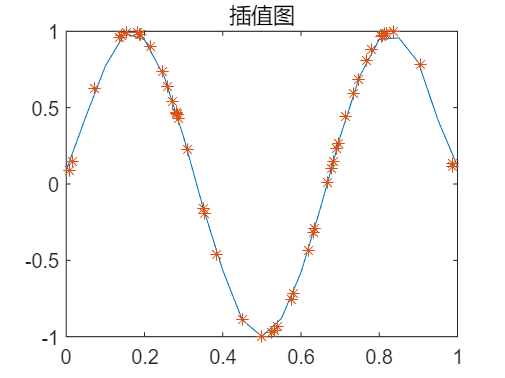

plot(xx,yy)
title('插值图')
hold on
plot(x,y,'*')

max(abs(yy-f(xx)))

ans = 0.1166